# Tutorial05 Image processing and Analysis of Diffusing Molecules

#### Notes

Objective: Learn how to import images into Matlab and display them.

Will also dicuss about convolution, an IMPT operation in image analysis.

Fact: our eyes and brains are constantly doing convolutions whenever we look at anything.

Fact: Many kinds of lab data are presented as 2D arrays of #s 

=> They can conveniently be represented to our brains as images. 

E.g. atomic force measurement data, computed tomography data

Why is basic manipulation useful?

Because it helps us make images meaningful to humans.

2.. Images are Arrays of Numbers, aka Matrices.

**Fact**. Matlab can import and display images.

An image is just a 2D array of #s.

-> Therefore, we can take advantage of all of Matlab's fns to do calculations on the data that the image represent.

TO DO SO, we need to give Matlab access to some image data.

% load the image
A = imread('bwEmily.tiff');

If no semicolon, will get:

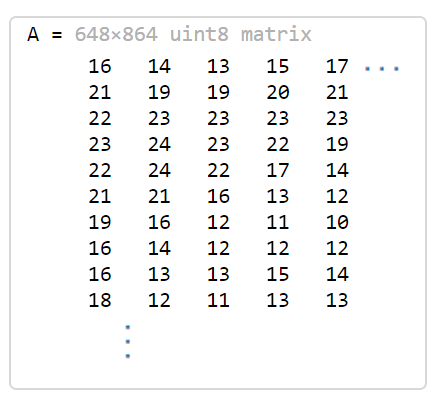

The array A arrives in a numeric format that Matlab finds inconvenient. So before proceeding, 

% convert the numeric format into a more usual form
A = single(A);

To view a black and white image, need to specify colourmap:

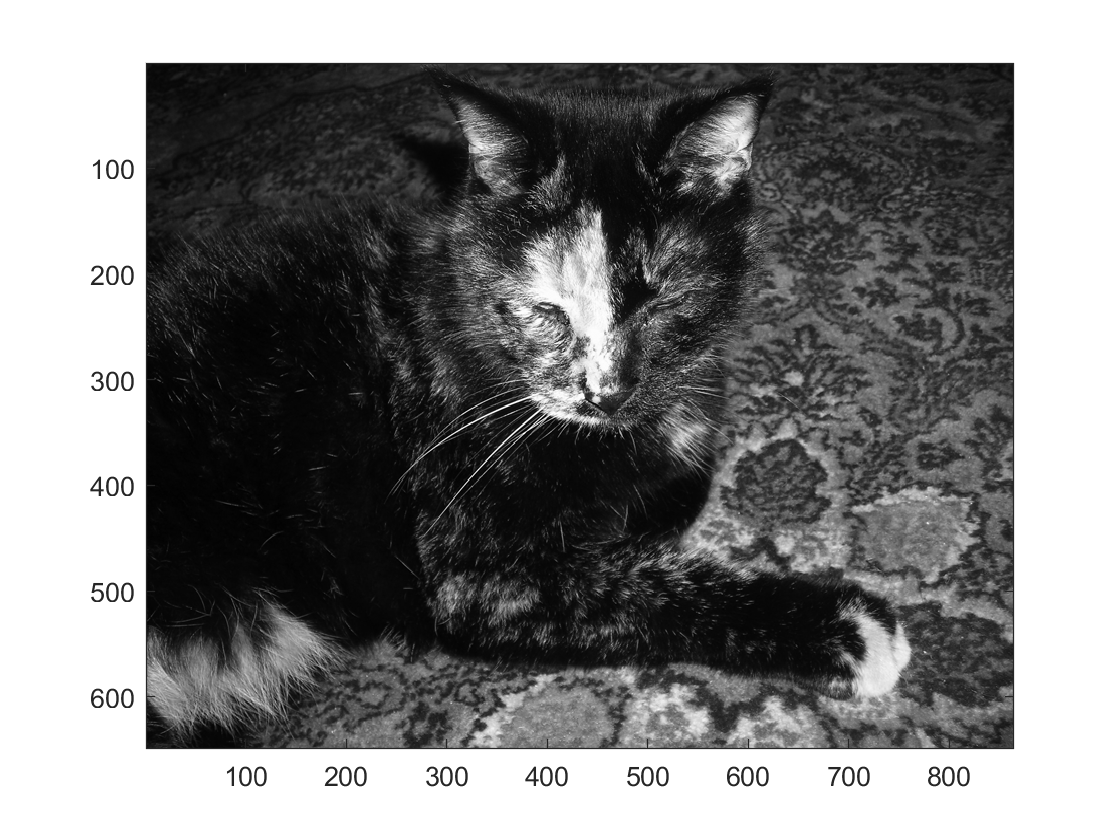

% specify colourmap
co = [0:255]/256;
colormap([co;co;co]');

(Notice the punctuation!) The **values of co** tell Matlab how brightly to illuminate each pixel for each allowed value in the image.

Note: The list appears three times in colormap because, for a grayscale image, we always want equal amounts of red, green, and blue 

Here, we've made a trivial (linear) choice; other choices would distort the image in interesting ways.

Having set the colourmap, use

% display the image
image(A)

3.. Convolution

Matlab defines the convolution C of an image I with a filter F as a new array of numbers:

where the ranges of the sums are over all values of k that refer to legal entries of both F and I. That is, all indices must be larger than zero and not larger than the size f their respective arrays.

4.. Averaging

The simplest filter we can choose assigns the same weight to each pixel in a fixed range. Make a 3x3 array F in which each element equals 1/9 

- Use the conv2 command to convolve the new filter with the image I downloaded and display the result.

F = zeros(3,3);
a = 1/9

a = 0.1111

F = [a a a; a a a; a a a]

F =     0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111



figure;
colormap([co;co;co]')

conv2(F, A)

ans = 650×866 single matrix
    1.7778    3.3333    4.7778    4.6667    5.0000    5.2222    4.7778    4.2222    4.1111    4.5556    4.8889    5.0000    5.0000    5.3333    5.5556    5.5556    5.3333    5.2222    5.3333    5.2222    5.1111    5.0000    5.0000    4.8889    4.6667    4.5556    4.3333    4.0000    3.3333    3.0000    3.0000    3.3333    3.6667    4.1111    4.5556    5.0000    5.2222    5.1111    4.7778    4.3333    4.0000    3.6667    3.4444    3.5556    3.8889    4.0000    3.7778    3.4444    3.5556    3.8889
    4.1111    7.7778   11.3333   11.1111   11.6667   11.6667   10.2222    8.5556    8.1111    9.0000    9.8889   10.2222   10.4444   10.7778   11.0000   10.8889   10.6667   10.5556   10.6667   10.4444   10.2222   10.0000   10.0000    9.6667    9.2222    8.7778    8.2222    7.4444    6.3333    5.7778    5.7778    6.2222    6.7778    7.5556    8.6667   10.0000   11.0000   11.1111   10.3333    9.1111    8.0000    7.1111    6.6667    6.8889    7.4444    7.7778    7.5556 